**Supervised learning for modulation classification data trained at SNR 30 dB and testing at various SNR's 0,5,10,15,20,25 and 30 dB.**

Setting the parameters and loading the complete dataset at **SNR 30 dB.**

rng(1235)
modulationTypes = categorical(["BPSK", "QPSK","16QAM","64QAM"]);
numFramesPerModType = 500;
percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
numModulationTypes = length(modulationTypes);
dataDirectory = fullfile(tempdir,"labelled30");
disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled30


Spilitting the data into training,testing and validation dataset.

frameDS = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTrans = transform(frameDS,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTrans,validDSTrans,testDSTrans] = helperModClassSplitData(frameDSTrans,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 24 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 41 sec



trainFramesTall = tall(transform(trainDSTrans, @helperModClassReadFrame));
rxTrainFrames = gather(trainFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 8.6 sec
Evaluation completed in 8.7 sec


rxTrainFrames = cat(4, rxTrainFrames{:});

trainLabelsTall = tall(transform(trainDSTrans, @helperModClassReadLabel));
rxTrainLabels = gather(trainLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 9.9 sec
- Pass 2 of 2: Completed in 20 sec
Evaluation completed in 31 sec



validFramesTall = tall(transform(validDSTrans, @helperModClassReadFrame));
rxValidFrames = gather(validFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3 sec
Evaluation completed in 3.1 sec


rxValidFrames = cat(4, rxValidFrames{:});

validLabelsTall = tall(transform(validDSTrans, @helperModClassReadLabel));
rxValidLabels = gather(validLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.8 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.4 sec



testFramesTall = tall(transform(testDSTrans, @helperModClassReadFrame));
rxTestFrames = gather(testFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.6 sec
Evaluation completed in 2.6 sec


rxTestFrames = cat(4, rxTestFrames{:});

testLabelsTall = tall(transform(testDSTrans, @helperModClassReadLabel));
rxTestLabels = gather(testLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.6 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.2 sec


Training a neural network(Convolutional neural network).

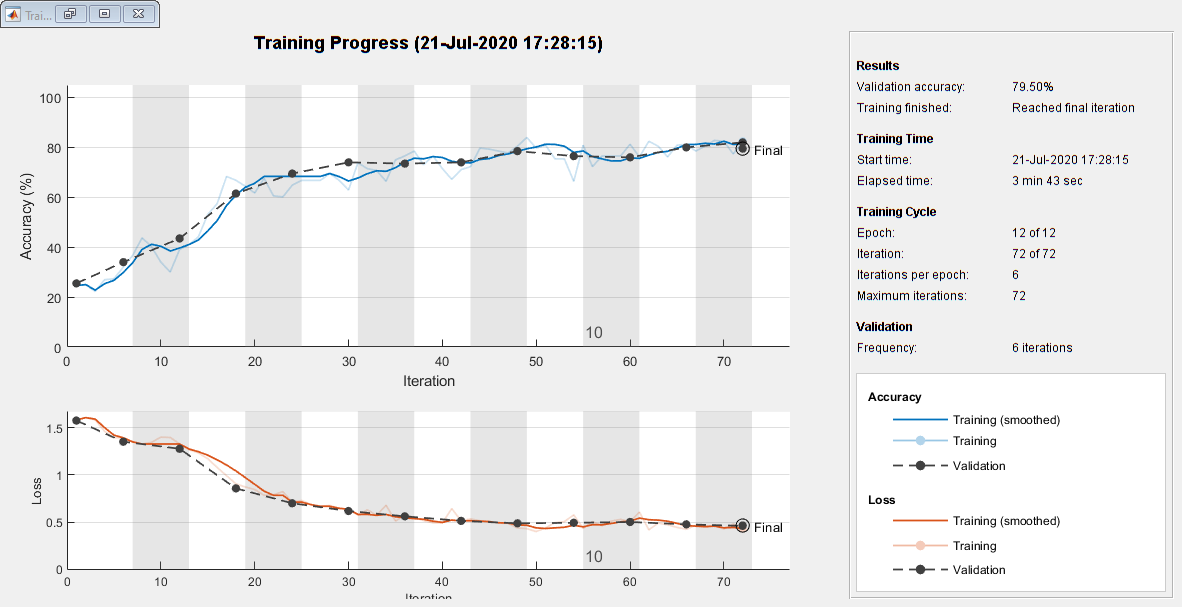

modClassNet = helperModClassCNN(modulationTypes,sps,spf);
maxEpochs = 12;
miniBatchSize = 256;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels);
trainedNet = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet,options);

Loading each directory at various SNR's i.e **0,5,10,15,20,25,30 dB** test data

Printing the accuracy at each stage for each SNR 

The above trained network is used as a supervised classifier.

dataDirectory = fullfile(tempdir,"labelled0")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled0"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled0



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 16 sec
- Pass 2 of 2: Completed in 18 sec
Evaluation completed in 36 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.5 sec
Evaluation completed in 2.6 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.7 sec
- Pass 2 of 2: Completed in 3.3 sec
Evaluation completed in 6.7 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.2500

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled5")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled5"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled5



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 11 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 26 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.7 sec
Evaluation completed in 2.7 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.3 sec
- Pass 2 of 2: Completed in 4.1 sec
Evaluation completed in 8.1 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.2550


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dataDirectory = fullfile(tempdir,"labelled10")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled10"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled10



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 11 sec
- Pass 2 of 2: Completed in 14 sec
Evaluation completed in 26 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.6 sec
Evaluation completed in 2.6 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.5 sec
- Pass 2 of 2: Completed in 3.2 sec
Evaluation completed in 6.3 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.3900


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dataDirectory = fullfile(tempdir,"labelled15")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled15"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled15



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 13 sec
- Pass 2 of 2: Completed in 16 sec
Evaluation completed in 30 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.4 sec
Evaluation completed in 2.5 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.5 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.2 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.6050

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled20")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled20"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled20



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 11 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 26 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.7 sec
Evaluation completed in 2.7 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.3 sec
- Pass 2 of 2: Completed in 3.1 sec
Evaluation completed in 7.4 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.7100

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled25")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled25"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled25



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 15 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 31 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.5 sec
Evaluation completed in 2.6 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.5 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.2 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.8050

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled30")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled30"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled30



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 11 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 26 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3.1 sec
Evaluation completed in 3.1 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.5 sec
- Pass 2 of 2: Completed in 2.9 sec
Evaluation completed in 6.1 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.7950

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
